On this section we are going to compare two different egde detection filters.

One of them will be a linear filtering using a 3 by 3 kernel and the second one will be a commonly used edge detection known as Canny Edge Detector. Lastly we will try to re-create such algorithm.

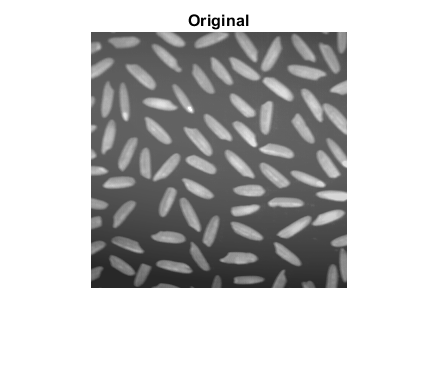

I = imread('rice.tif');

imshow(I), title('Original')

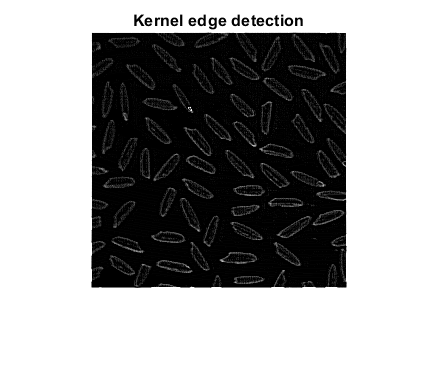

eKernel = [-1 -1 -1; -1 8 -1; -1 -1 -1];
eI = imfilter(I, eKernel);
imshow(eI), title('Kernel edge detection')

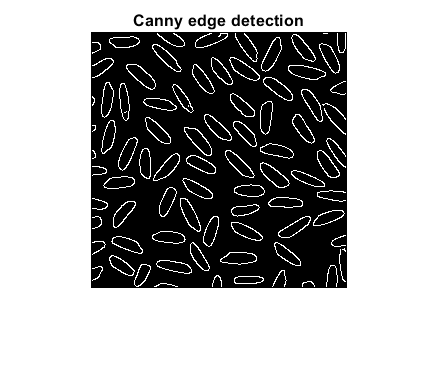

cI = edge(I,'Canny');
imshow(cI), title('Canny edge detection')

Here we can see that the Canny detection results with a more shaprened edge with less noise edge detection. This mainly due to the Non-maximum suppression funciton used in it. This funtion only uses the most dominant pixel of the neighbourhood of edges as an edge. In addition Hysteresis Thresholding also plays a role in the edge deteciton, including a low and a high threshold on the fucntion, the final edge detection will result with a complete outline of the objects. These two funtions will be explained in futher detail in the next section.

These are the steps taken in Canny edge detection:

- Smooth image with Gaussian filter

- Apply derivative of Gaussian

- Find magnitude and orientation of gradient

- Non-maximum suppression

- Hysteresis Thresholding

Now that we know the basis of Canny edge detection, we can program our own edge detection

We first start by applying the Guassian filter on the image to smooth it.

J = imgaussfilt(I, 0.1);

In this step we calculte the gradient of the smoothed picture.

This step is also know as the Sobel operator, which is another well known edge detection algorithm. The Sobel operator computes an approximation of the gradient magnitude of an image. This is font by firtsly calculating the directional gradient on the x direction (which will result on an 'edge deteciton' going vertically) and a directional gradient on the y direction (result on 'edge detection' of horizontal lines). These results can be found on the image below.

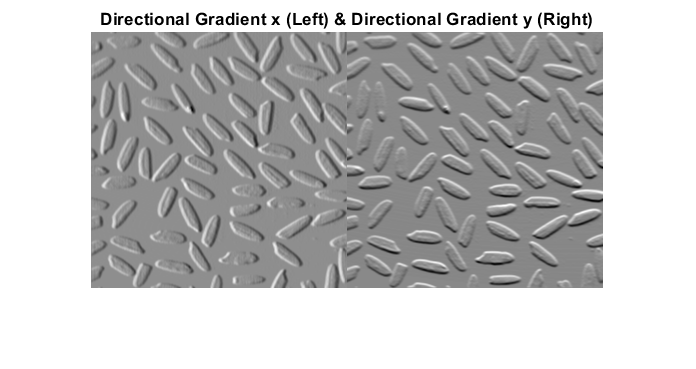

[Gx,Gy] = imgradientxy(J);
imshowpair(Gx, Gy, 'montage'), title('Directional Gradient x (Left) & Directional Gradient y (Right)');

Once we calculate the direcitonal gradient of both axis we can esaily calulate the gradient magnitue with a simple pythagoras theorem formua: $\mathrm{Gmag}=\;\sqrt{{\mathrm{Gx}}^2 +{\mathrm{Gy}}^2 }$ and the gradient direciton: $\mathrm{Gdir}\;=\;\mathrm{arctan}\left(\frac{\mathrm{Gx}}{\mathrm{Gy}}\right)$.

The gradient magnitude reults on .... and the gradient direction results on ...

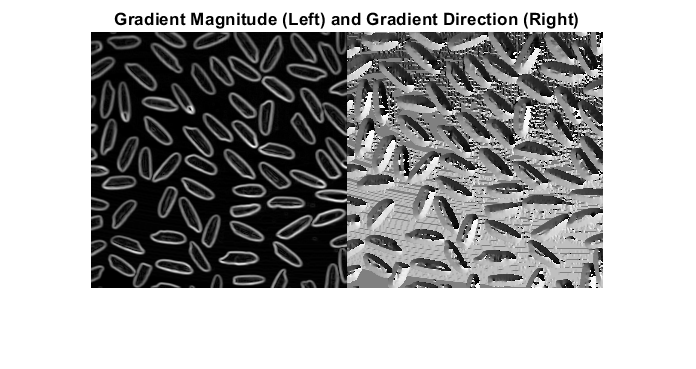

[Gmag,Gdir] = imgradient(Gx,Gy);
imshowpair(Gmag,Gdir,'montage'), title('Gradient Magnitude (Left) and Gradient Direction (Right)')

Non-Maximum Suppresion

K = Gmag;
for y = 1: size(K, 1)
    for x = 1: size(K, 2)
        if y == 0 || y == size(K, 1) -1 || x == 0 || x == size(K, 2) -1
            K(x, y) = 0;
        end
        if Gtheta == 0
            if K(x, y) <= K(x, y-1) || K(x, y) <= K(x, y+1)
                K(x,y) = 0;
            end
        end
        if Gtheta == 1
            if K(x, y) <= K(x-1, y+1) || K(x, y) <= K(x+1, y-1)
                K(x,y) = 0;
            end
        end
        if Gtheta == 2
            if K(x, y) <= K(x-1, y) || K(x, y) <= K(x+1, y)
                K(x,y) = 0;
            end
        end
        if Gtheta == 2
            if K(x, y) <= K(x-1, y-1) || K(x, y) <= K(x+1, y+1)
                K(x,y) = 0;
            end
        end
    end
end


Hystersis Thresholding

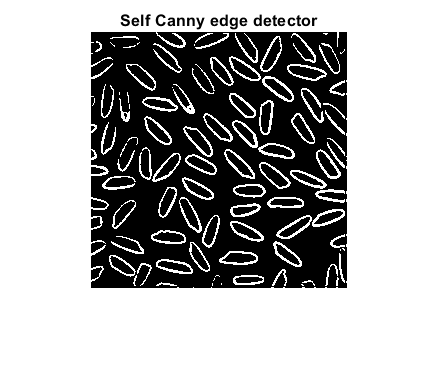

L = hysteresis3d(K, 0.355, 15, 4);
imshow(L), title('Self Canny edge detector')